This script is used to generate the figure of running vs resting data.

It is supposed to be used after running the FLP analysis of the running vs resting experiment.

And then it will read the speed and timestamp information from the csv files. And then plot the time, speed, and FLP recording together.

cd('/Volumes/PcSSDA/RvR/20220328_1630_RvR_001')
ExperimentName='20220328_1630_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='1630';
Recording='1';

Recording = '1'


analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

cd('/Volumes/PcSSDA/RvR/20220404_1630_RvR_002')
ExperimentName='20220404_1630_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

mouse='1630';
Recording='2';

Recording = '2'

cd('/Volumes/PcSSDA/RvR/20220404_1630_RvR_003')
ExperimentName='20220404_1630_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
analysis_name=[ExperimentName,'_analysis_'];

mouse='1630';
Recording='3';

Recording = '3'

cd('/Volumes/PcSSDA/RvR/20220328_1629_RvR_001')
ExperimentName='20220328_1629_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1629';
Recording='1';


cd('/Volumes/PcSSDA/RvR/20220404_1629_RvR_002')
ExperimentName='20220404_1629_RvR_002';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1629';
Recording='2';

cd('/Volumes/PcSSDA/RvR/20220404_1629_RvR_003')
ExperimentName='20220404_1629_RvR_003';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1629';
Recording='3';

cd('/Volumes/PcSSDA/RvR/20220328_1627_RvR_001')
ExperimentName='20220328_1627_RvR_001';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1627';
Recording='1';

cd('/Volumes/PcSSDA/RvR/20220329_1627_RvR_002')
ExperimentName='20220329_1627_RvR_002';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1627';
Recording='2';

cd('/Volumes/PcSSDA/RvR/20220325_1612_RvR_001')
ExperimentName='20220325_1612_RvR_001';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1612';
Recording='1';

cd('/Volumes/PcSSDA/RvR/20220330_1612_RvR_002')
ExperimentName='20220330_1612_RvR_002';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1612';
Recording='2';

cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_003')
ExperimentName='20220325_1610_RvR_001';% Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1610';
Recording='1';

cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_003')
ExperimentName='20220330_1610_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='1610';
Recording='3';

cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
mouse='123';
Recording='1';

i=1;
filename=[analysis_name,num2str(i),'_20220403.mat'];
load(filename)

i=1;
filename=[analysis_name,num2str(i),'_20220512.mat'];
load(filename)

i=1;
filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

speed_csv=['speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

speed_csv=['timestamp_speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-07-14 16:01:04.9521152'

reference_time=datetime(reference_time)

reference_time = datetime
   14-Jul-2022 16:01:04



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);


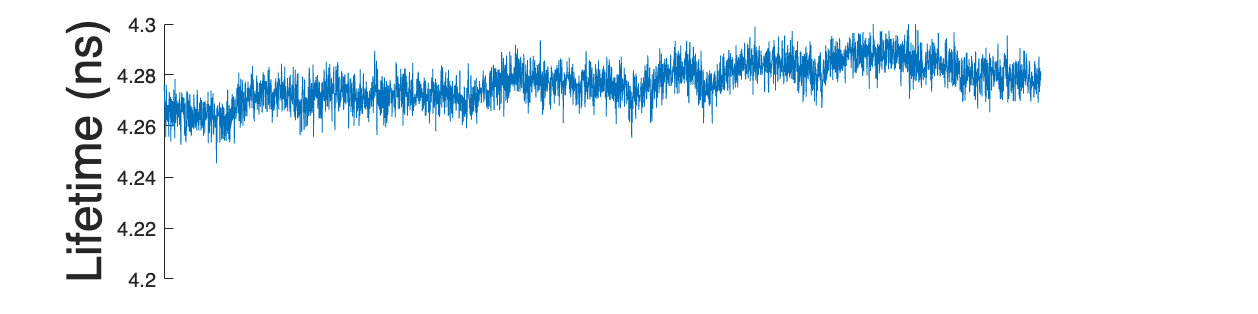

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20;
% yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
ylim([4.2 4.3])
ax.XAxis.Visible = 'off';
box off

% yticks([4.15 4.20 4.25 4.3])


figure2=figure;
figure2.Position=[10 10 1200 300];
% yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
% legend('Lifetime','Speed','FontSize',20)
title([mouse ' ' Recording])

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


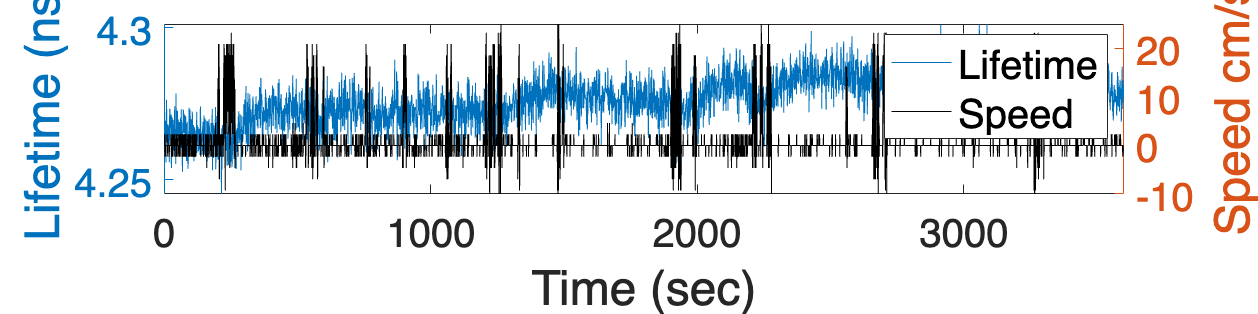

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
% ylim([4.15 4.25])
% yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed,'Color', [0 0 0 0])
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Lifetime','Speed','FontSize',20)

% title([mouse ' ' Recording])


figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.110000000000000 0.775000000000000 0.815000000000000]
            Units: 'normalized'

  Show all properties


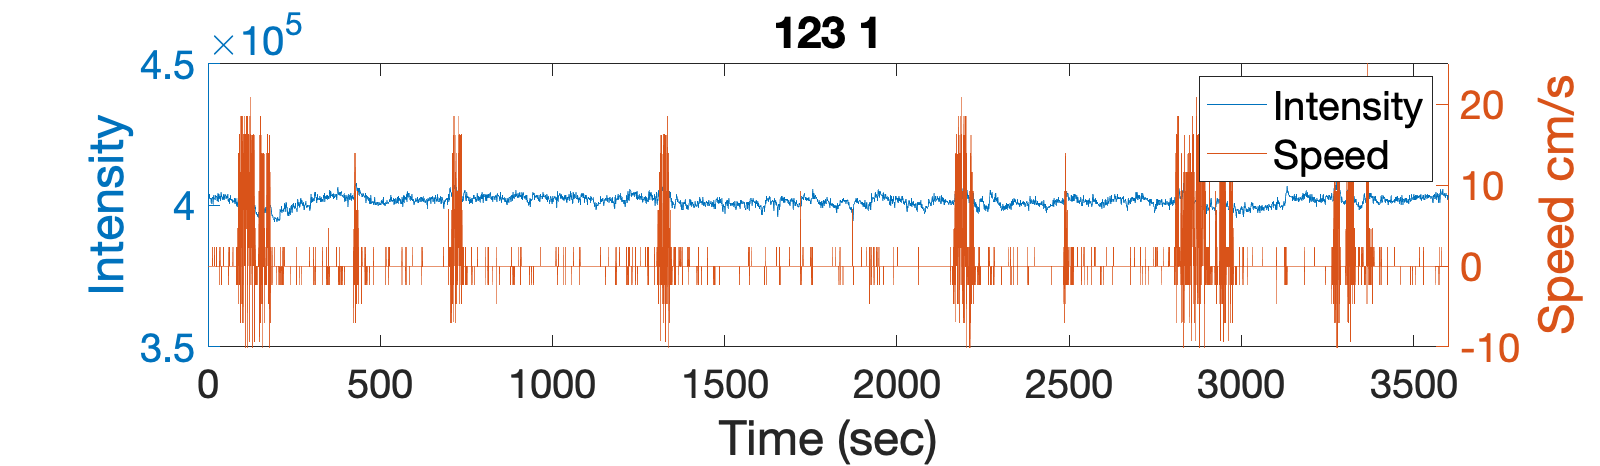

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
ylim([350000 450000])
% yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Intensity','Speed','FontSize',20)
title([mouse ' ' Recording])